# Test 2

## Problem 1


% a)
rng('shuffle')

C=randi([1,20],1,2)

C =     10     7



m=C(1), k=C(2), b=min(C)

m = 10

k = 7

b = 7

% mx’  + bx’ + kx = bsin(wt).
syms r omega t F0
omega=sym('omega','real')

$$omega = \omega$$

omega=sym('omega','positive')

$$omega = \omega$$

t=sym('t','real')

$$t = t$$


F0=b

F0 = 7

p(r)=1*r^2+6*r+25

$$p(r) = r^{2}+6\,r+25$$

zpsol=F0*exp(i*omega*t)/p(i*omega)

$$zpsol = \frac{7\,{\mathrm{e}}^{\omega \,t\,\mathrm{i}}}{-\omega^{2}+6\,\omega \,\mathrm{i}+25}$$

gabs=simplify(abs(zpsol))

$$gabs = \frac{7}{\sqrt{{\left(\omega^{2}-25\right)}^{2}+36\,\omega^{2}}}$$

c1=imag(zpsol)

$$c1 = -\frac{7\,\sin\left(\omega \,t\right)\,\left(\omega^{2}-25\right)}{{\left(\omega^{2}-25\right)}^{2}+36\,\omega^{2}}-\frac{42\,\omega \,\cos\left(\omega \,t\right)}{{\left(\omega^{2}-25\right)}^{2}+36\,\omega^{2}}$$

c2=real(zpsol)

$$c2 = \frac{42\,\omega \,\sin\left(\omega \,t\right)}{{\left(\omega^{2}-25\right)}^{2}+36\,\omega^{2}}-\frac{7\,\cos\left(\omega \,t\right)\,\left(\omega^{2}-25\right)}{{\left(\omega^{2}-25\right)}^{2}+36\,\omega^{2}}$$


g=(sqrt(c1^2+c2^2))

$$g = \begin{array}{l} 7\,\sqrt{\frac{{\left(\frac{42\,\omega \,\sin\left(\omega \,t\right)}{\sigma_{1}}-\frac{7\,\cos\left(\omega \,t\right)\,\left(\omega^{2}-25\right)}{\sigma_{1}}\right)}^{2}}{49}+\frac{{\left(\frac{7\,\sin\left(\omega \,t\right)\,\left(\omega^{2}-25\right)}{\sigma_{1}}+\frac{42\,\omega \,\cos\left(\omega \,t\right)}{\sigma_{1}}\right)}^{2}}{49}}\\ \mathrm{where}\\ \sigma_{1}={\left(\omega^{2}-25\right)}^{2}+36\,\omega^{2} \end{array}$$

gain=simplify(g)

$$gain = \frac{7}{\sqrt{\omega^{4}-14\,\omega^{2}+625}}$$


eq1=diff(g,omega)

$$eq1 = \begin{array}{l} \frac{7\,\left(\frac{2\,\sigma_{2}\,\left(\frac{42\,\sin\left(\omega \,t\right)}{\sigma_{4}}-\frac{14\,\omega \,\cos\left(\omega \,t\right)}{\sigma_{4}}-\frac{42\,\omega \,\sin\left(\omega \,t\right)\,\sigma_{1}}{{\sigma_{4}}^{2}}+\frac{7\,t\,\sin\left(\omega \,t\right)\,\left(\omega^{2}-25\right)}{\sigma_{4}}+\frac{42\,\omega \,t\,\cos\left(\omega \,t\right)}{\sigma_{4}}+\frac{7\,\cos\left(\omega \,t\right)\,\sigma_{1}\,\left(\omega^{2}-25\right)}{{\sigma_{4}}^{2}}\right)}{49}+\frac{2\,\sigma_{3}\,\left(\frac{42\,\cos\left(\omega \,t\right)}{\sigma_{4}}+\frac{14\,\omega \,\sin\left(\omega \,t\right)}{\sigma_{4}}-\frac{42\,\omega \,\cos\left(\omega \,t\right)\,\sigma_{1}}{{\sigma_{4}}^{2}}+\frac{7\,t\,\cos\left(\omega \,t\right)\,\left(\omega^{2}-25\right)}{\sigma_{4}}-\frac{42\,\omega \,t\,\sin\left(\omega \,t\right)}{\sigma_{4}}-\frac{7\,\sin\left(\omega \,t\right)\,\sigma_{1}\,\left(\omega^{2}-25\right)}{{\sigma_{4}}^{2}}\right)}{49}\right)}{2\,\sqrt{\frac{{\sigma_{2}}^{2}}{49}+\frac{{\sigma_{3}}^{2}}{49}}}\\ \mathrm{where}\\ \sigma_{1}=72\,\omega +4\,\omega \,\left(\omega^{2}-25\right)\\ \sigma_{2}=\frac{42\,\omega \,\sin\left(\omega \,t\right)}{\sigma_{4}}-\frac{7\,\cos\left(\omega \,t\right)\,\left(\omega^{2}-25\right)}{\sigma_{4}}\\ \sigma_{3}=\frac{7\,\sin\left(\omega \,t\right)\,\left(\omega^{2}-25\right)}{\sigma_{4}}+\frac{42\,\omega \,\cos\left(\omega \,t\right)}{\sigma_{4}}\\ \sigma_{4}={\left(\omega^{2}-25\right)}^{2}+36\,\omega^{2} \end{array}$$

solve(eq1,omega)

$$ans = \sqrt{7}$$


wres = sqrt(k/m-2*(b/(2*m))^2)

wres = 0.6745

fprintf("b) The resonance frequency is %4.4f%+4.4fi.",real(wres),imag(wres))

b) The resonance frequency is 0.6745+0.0000i.


fprintf("c) The complex gain is %s \n and the absolute value of this gain is %s",zpsol,gabs)

c) The complex gain is (7*exp(omega*t*1i))/(omega*6i - omega^2 + 25) 
 and the absolute value of this gain is 7/((omega^2 - 25)^2 + 36*omega^2)^(1/2)


fprintf("d) The gain frequency is %s ",gain)

d) The gain frequency is 7/(omega^4 - 14*omega^2 + 625)^(1/2) 

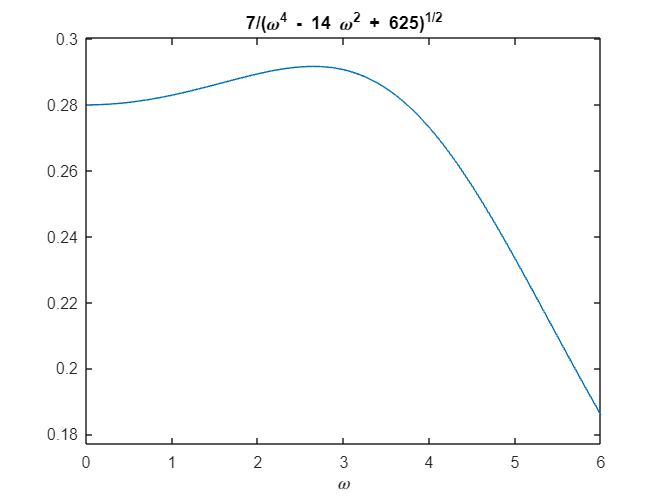


ezplot(gain,[0,6]) %ploted as a function of w (omega)

## Problem 2

% a)
clear all

rng('shuffle')

a=randi([-10,10])

a = 4

%x' =Ax
syms t c1 c2
A=[a,2; -2,a] 

A =      4     2
    -2     4


[v,d]=eig(sym(A))

$$v = \left(\begin{array}{cc} \mathrm{i} & -\mathrm{i}\\ 1 & 1 \end{array}\right)$$

$$d = \left(\begin{array}{cc} 4-2\,\mathrm{i} & 0\\ 0 & 4+2\,\mathrm{i} \end{array}\right)$$

real(v(:,1))

$$ans = \left(\begin{array}{c} 0\\ 1 \end{array}\right)$$

a_vec=real(v(:,1))

$$a\_vec = \left(\begin{array}{c} 0\\ 1 \end{array}\right)$$

b_vec=imag(v(:,1))

$$b\_vec = \left(\begin{array}{c} 1\\ 0 \end{array}\right)$$

alpha=real(d(1,1))%real part of 1st eigenvalue

$$alpha = 4$$

beta=imag(d(1,1))%imaginary part of 1st eigenvalue

$$beta = -2$$

solnx1=exp(alpha*t)*(a_vec*cos(beta*t)-b_vec*sin(beta*t))

$$solnx1 = \left(\begin{array}{c} \sin\left(2\,t\right)\,{\mathrm{e}}^{4\,t}\\ \cos\left(2\,t\right)\,{\mathrm{e}}^{4\,t} \end{array}\right)$$

solnx2=exp(alpha*t)*(a_vec*sin(beta*t)+b_vec*cos(beta*t))

$$solnx2 = \left(\begin{array}{c} \cos\left(2\,t\right)\,{\mathrm{e}}^{4\,t}\\ -\sin\left(2\,t\right)\,{\mathrm{e}}^{4\,t} \end{array}\right)$$

%solnx1 and solnx2 are from Eq.(5.75)
soln=c1*solnx1+c2*solnx2

$$soln = \left(\begin{array}{c} c_{2}\,\cos\left(2\,t\right)\,{\mathrm{e}}^{4\,t}+c_{1}\,\sin\left(2\,t\right)\,{\mathrm{e}}^{4\,t}\\ c_{1}\,\cos\left(2\,t\right)\,{\mathrm{e}}^{4\,t}-c_{2}\,\sin\left(2\,t\right)\,{\mathrm{e}}^{4\,t} \end{array}\right)$$

fprintf("b) The eigenvalues for the coefficient matrix A are alpha = %4i and beta = %4i", alpha, beta)

b) The eigenvalues for the coefficient matrix A are alpha =    4 and beta =   -2

fprintf("The eigenvectors for the coefficient matrix A is %s and %s for alpha in a colomn.\nThe eigenvectors for the coefficient matrix A is %s and %s for beta in a colomn.",a_vec(1),a_vec(2),b_vec(1),b_vec(2))

The eigenvectors for the coefficient matrix A is 0 and 1 for alpha in a colomn.
The eigenvectors for the coefficient matrix A is 1 and 0 for beta in a colomn.


fprintf("c) The formula is %s",soln)

c) The formula is c2*cos(2*t)*exp(4*t) + c1*sin(2*t)*exp(4*t)c) The formula is c1*cos(2*t)*exp(4*t) - c2*sin(2*t)*exp(4*t)